# Sessió 10 

Yimin Pan, Santi Otin

## Llegir les imatges

clc; clear;

erableNames = dir('Erable\*.jpg');
faigNames = dir('Faig\*.jpg');
roureNames = dir('Roure\*.jpg');
for i=1:length(erableNames)
   erableImgs{i} = imread(fullfile(erableNames(i).folder,'\',erableNames(i).name));
   faigImgs{i} = imread(fullfile(faigNames(i).folder,'\',faigNames(i).name));
   roureImgs{i} = imread(fullfile(roureNames(i).folder,'\',roureNames(i).name));
end

## Descriptors de Fourier

Labels = []; % Tags de les imatges
FD = []; % Feature Matrix (Fourier Descriptor)
N = 25; % Nombre de descriptors
resize = 1/16;

for i=1:length(erableImgs)
    im = erableImgs{i};
    im=imresize(im,resize);
    im = im2bw(im);
    im = ~im;
    %Extreure contorn
    ero=imerode(im,strel('disk',1));
    cont=xor(ero,im);
    [fila col] = find(im,1);
    B = bwtraceboundary(im,[fila col],'E');
    aux=zeros(size(im));
    %Calcular descriptor de Fourier
    mig=mean(B);
    B(:,1)=B(:,1)-mig(1);
    B(:,2)=B(:,2)-mig(2);
    s= B(:,1) + 1i*B(:,2);
    [mida,~]=size(B);
    if(mida/2~=round(mida/2))
        s(end+1,:)=s(end,:);
        mida=mida+1;
    end
    %Les imatges tenen diferent mida, per tant el nombre de descriptors
    %resultant també serà diferent. Pero podem forçar un mateix nombre per
    %tots
    z=fft(s, N);
    % Convertir el complex com 2 features (real e imaginari) ja que el
    % learner no es compatible amb els complexos
    z2 = [real(z) imag(z)];
    z2 = reshape(z2.',1,[]);
    FD = [FD; z2];
    Labels = [Labels; "erable"];
    
end


% Mateix proces per les altre tipus de fulles
for i=1:length(faigImgs)
    im = faigImgs{i};
    im=imresize(im,resize);
    im = im2bw(im);
    im = ~im;
    %Extreure contorn
    ero=imerode(im,strel('disk',1));
    cont=xor(ero,im);
    [fila col] = find(im,1);
    B = bwtraceboundary(im,[fila col],'E');
    aux=zeros(size(im));
    %Calcular descriptor de Fourier
    mig=mean(B);
    B(:,1)=B(:,1)-mig(1);
    B(:,2)=B(:,2)-mig(2);
    s= B(:,1) + 1i*B(:,2);
    [mida,~]=size(B);
    if(mida/2~=round(mida/2))
        s(end+1,:)=s(end,:);
        mida=mida+1;
    end
    z=fft(s, N);
    z2 = [real(z) imag(z)];
    z2 = reshape(z2.',1,[]);
    FD = [FD; z2];
    Labels = [Labels; "faig"];
end

for i=1:length(roureImgs)
    im = roureImgs{i};
    im=imresize(im,resize);
    im = im2bw(im);
    im = ~im;
    %Extreure contorn
    ero=imerode(im,strel('disk',1));
    cont=xor(ero,im);
    [fila col] = find(im,1);
    B = bwtraceboundary(im,[fila col],'E');
    aux=zeros(size(im));
    %Calcular descriptor de Fourier
    mig=mean(B);
    B(:,1)=B(:,1)-mig(1);
    B(:,2)=B(:,2)-mig(2);
    s= B(:,1) + 1i*B(:,2);
    [mida,~]=size(B);
    if(mida/2~=round(mida/2))
        s(end+1,:)=s(end,:);
        mida=mida+1;
    end
    z=fft(s, N);
    z2 = [real(z) imag(z)];
    z2 = reshape(z2.',1,[]);
    FD = [FD; z2];
    Labels = [Labels; "roure"];
end

T = array2table(FD);
T = addvars(T, Labels, 'Before',1);

## Feature Vector

El vector de caracteristiques és el descriptor de Fourier del contorn de la imatge corresponent, amb N com el nombre de descriptors. LLavors la mida d'aquest vector es 2N, ja que hem separat cada descritor complex en part imaginaria y real, la raó és que el "Clasification Learner" no es capaç de tractar els complexos.

## Experiment i Resultat

Donat que les mostres están bastant bé equilibrats (1/3 de cada tipus de fulla), la precisió és un bón indicador del rendiment del clasificador. Per tant no farà falta servir altres indicadors com f-score.

Per evitar overfitting y evitar resultar en una falsa precisió alta, tots el procesos de validació es faràn amb cross-validation (5-folds).

S'han fet experiements amb diferent nombres de descriptors (N). Altra manera de fer-ho és deixar una N suficientment gran i després en la part de Feature Selection seleccionar els que volem testejar peró degut al alt nombre de descriptors aquesta forma no molt viable.

- N = 25: precisió del 93.8% per les Arbres de decisió, 79.5% per Naive Bayes i 95.8% pels métodes ensamblats.

- N = 50: precisió del 87.5% per les Arbres de decisió, 79.5% per Naive Bayes i 95.8% pels métodes ensamblats.

- N = 150: precisió del 81.3% per les Arbres de decisió, 87.5% per Naive Bayes i 91.7% pels métodes ensamblats.

- N = 250: precisió del 75% per les Arbres de decisió, 80% per Naive Bayes i 91% pels métodes ensamblats.

- N = 500:  precisió del 79.2% per les Arbres de decisió, 81.3% per Naive Bayes i 89% pels métodes ensamblats.

- N = 750:  precisió del 68.8% per les Arbres de decisió, 85.4% per Naive Bayes i 89.6% pels métodes ensamblats.

En la sesió anterior hem aprés que quan més descriptors tenim, la imatge és més detallada. Peró en aquest experiments podem veure que més no és millor, la raó és que en machine learning existeix el que es diu "curse of dimensionality". Quan tenim un nombre molt alt de features (200, 500 ...), l'espai de característiques es torna molt dispers i aixó es molt problemátic pels métodes que requereixen estadística. La solució seria aumentar el nombre de samples, peró en aquest cas no es possible, per a que podem veure que classificadors amb menys descriptors (N) sol tenim una millor rendiment.

A més quan la dimensionalitat augmenta, es requereix més temps d'entrenament.

Per tant, el millor resultat s'obté amb entre 25 i 50 descriptors, amb 95.8% de precisió amb Bagged Tree. I aquest es la matriu de confusió:

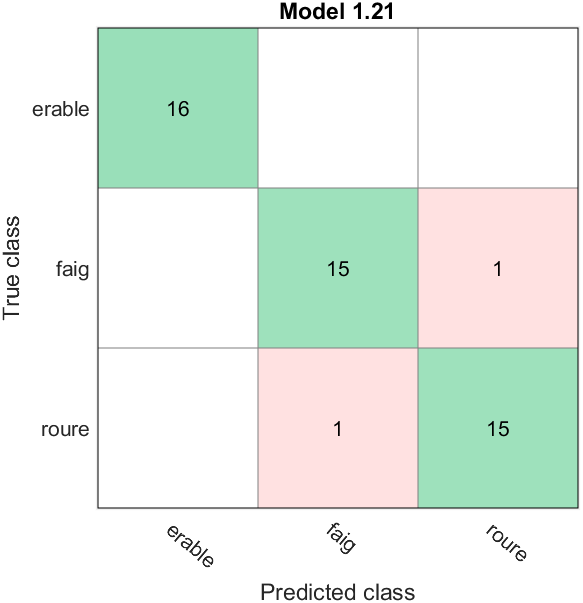

solament hem tingut 2 errors de clasificació.